% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

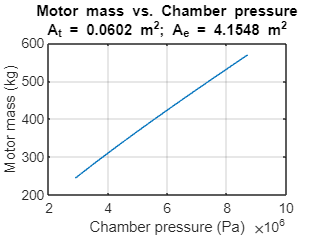

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

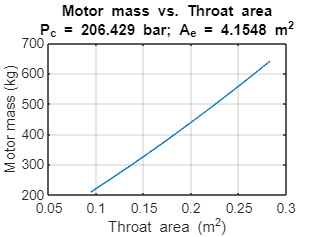


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

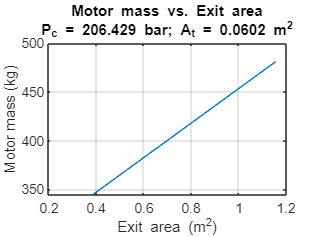


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

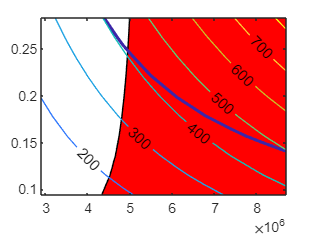

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    3.116809e+04     7.379e-02     1.000e+00     0.000e+00     2.655e+04  
    1           8    7.344014e+03     4.570e+00     1.000e+00     1.553e+00     3.175e+04  
    2          15    7.964865e+03     3.494e+00     3.430e-01     2.767e+00     2.004e+04  
    3          19    7.647320e+03     1.897e+00     1.000e+00     2.293e+00     1.358e+04  
    4          24    9.004992e+03     1.036e+00     7.000e-01     2.142e+00     1.074e+04  
    5          28    1.090781e+04     3.606e-01     1.000e+00     1.013e+00     1.662e+04  
    6          32    1.105504e+04     1.078e-01     1.000e+00     3.980e+00     1.350e+03  
    7          36    1.218566e+04     4.070e-02     1.000e+00     6.751e-01     1.934e+03  
    8          40    1.241758e+04     1.398e-03     1.000e+00     6.568e-02     6.

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 52
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.923148e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.791807e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.7918e-10
           stepsize: 4.4219e-04
       lssteplength: 1
      firstorderopt: 0.0088
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: -1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4364e+04
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1459198.337013
Throat area = 0.729036
Exit area = 6.010552
Total Mass = 12428.637510

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
tic
for i=1:100
x0 = lb + rand(size(lb)).*(ub - lb);
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)
x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)
if(i==1)
    fvalref=output.bestfeasible.fval;
    ssq=0
end
ssq=ssq+abs(output.bestfeasible.fval-fvalref);
end


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4       134013 

toc

%GA 
% tic
% [xout2, fval2, exitflag2, output2, lambda2] = ga(@calc_objective_test,3,A,b,Aeq,beq,lb,ub,@calc_constraints)
% toc